# Using Bode diagrams to assess the impact of discretisation on closed-loop behaviour

The purpose of this fille is to illustrate the impact of discretisation on closed-loop performance. Continuous time control design is well understood and thus a user may prefer to do this. However, will the compensator still be effective if the real implementation is in discrete time, as would be common place? It is seen below that the compensator may be effective if the sampling time is fast enough, but otherwise it may not be.

For simplicity this file assumes the system is discretised with the standard zero-order-hold (ZOH) and sampler. The compensator is discretised using Tustin's method. Gain and phase margins are used as indicators of the expected impact as the sample rate varies.

This live script needs the control toolbox. Once profficient, students will probably find that the methods used in this script are mostly performed using sisotool. 

The script assumes that students have gone through lag, lead and lead-lag design (**lead_design_with_bode.mlx,lead_lag_design_with_bode.mlx and lag_design_with_bode.mlx) **as any designs used within the case studies will have developed using those methods**. **This file takes those files as given and considers the impact on performance if the control implementation is discretised. Of particular interest is the impact of different discretisation rates.

### Similar files and the toolbox

See website below for more files like this.     [https://sites.google.com/sheffield.ac.uk/controleducation/matlabresources/section-6-11-community-control-toolbox](https://sites.google.com/sheffield.ac.uk/controleducation/matlabresources/section-6-11-community-control-toolbox)

This group of files can also be downloaded through MATLAB add-ons with the toolbox name:  **control101**

**For more information on those files uncomment and run either line of the code below:**

%  For documentation in a separate window type one of these 
%        Control101
%        doc Control101 Toolbox (pre 2024 only)
%        doc ("Control101 Toolbox")  
%        doc control101_toolbox. 
%  
%        help control101         (opens within the command window)

File written by J.A.Rossiter, University of Sheffield                         

## Table of contents

- Technical and mathematical background

- Typical examples

- Additional comments on Nyquist frequencies

## 1. Technical and mathematical background

This script assumes the following block diagram with system G(s) and compensator M(s). 

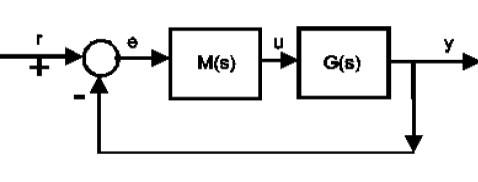

We can discretise the implementation within MATLAB code using the file*** c2d.m***:

- The discrete model is ***Gdiscrete = c2d(Gcontinuous,T)*** where T is the sample rate.

- The discrete controller is ***Mdiscrete = c2d(Mcontinuous,T,'tustin')*** where T is the sample rate.

We are particular interested into two factors.

- How does discretisation affect the Bode diagrams and phase margins? This in turn will impact on expected closed-loop performance.

- Are these expectations realised in the closed-loop simulations?

It is noted that in simplistic terms, in most cases the addition of the ZOH results in some phase lag and thus the phase is more negative than in the continuous time. This means worse phase margins and more oscillatory performance, or the need for a new compensator design (not discussed here).

It is not the purpose of this livescript to discuss design in the discrete domain, but solely to illustrate the dangers of mapping a continuous time domain to the discrete domain without understanding the possible repercussions. Nevertheless, readers may note that if sampling is fast enough, there is little difference, although that does not adequately discuss issues such as sensistivity to noise (outside the remit here).

#### Lead, lead-lag and lag compensator reminders: 

For a reminder on the design principles, please see the earlier files: **lead_design_with_bode.mlx, lead_lag_design_with_bode.mlx and lag_design_with_bode.mlx.**  Later on this file give an example of how those designs are impacted if the delay is known in advance but initially we take the designs as being done with the assumption that there is no delay.

## 2. Typical examples

This section uses some prefrabricated designs and simply compares the behaviour in continuous time with discrete time using various sampling rates. The plots have fixed domains to improve messaging. If you change the systems to selections of your own, you may need to change these domains.

**System 1 lag and lead-lag compensator**. Comment out lines below to select desired compensator.

G1=tf(1,[1 5 8 0]);
samplerate1 = [0,0.05,0.1,0.2,0.5];
desiredPM = 60;
eramp=0.2;
M1 = tf([7.2,.6],[1 0.015]);  % LAG ONLY
%M1 = tf([43,44],[1 4])*tf([1 0.2],[1 0.04]); % LEAD LAG

**System 2 lag specification for step offset and compensator**

G2=tf(1,[1 5 8]);
samplerate2 = [0,0.05,0.1,0.2,0.5];
desiredPM = 60;
ess=0.05;
M2=tf([25.6,11.5],[1,0.076]); %LAG

### 2.1 Bode and margins with and without discretisation

By drawing a vertical line at the gain cross-over frequency (0dB) which does not change, the user will note how the phase margin gets rapidly worse with growing sampling time. Comment out lines below to select the desired system.

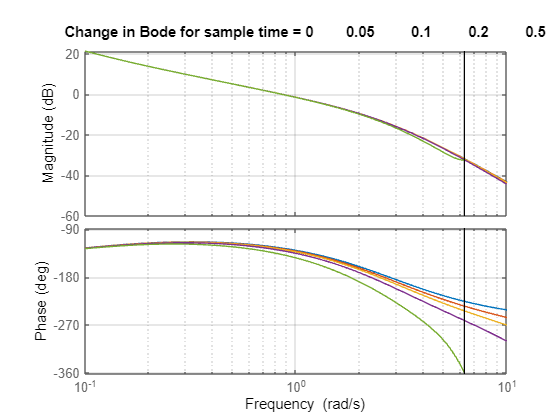

G=G1; M=M1; samplerate = samplerate1;
%G=G2; M=M2;samplerate = samplerate2;

figure;clf
nsample = length(samplerate);
Gsample=cell(1,nsample);
Gsample{1}=G; Msample{1}=M;
bode(G*M,{0.1,10});hold on
for k=2:nsample
    Gsample{k} = c2d(G,samplerate(k));
    Msample{k} = c2d(M,samplerate(k),'tustin');
    bode(Gsample{k}*Msample{k},{0.1,10}); hold on; grid on 
    [gm(k),pm(k)] = margin(Gsample{k}*Msample{k});
end
title(['Change in Bode for sample time = ',num2str(samplerate)])

disp(['Phase margin changes with sample time: PM =  ',num2str(pm)])

Phase margin changes with sample time: PM =  0      53.6796      52.4595      50.0375      42.9569


### 2.2 Step responses

The colour scheme for these plots matches those from the Bode diagram. From this it is clear that as the PM gets smaller, the overshoot, damping and convergence gets worse.

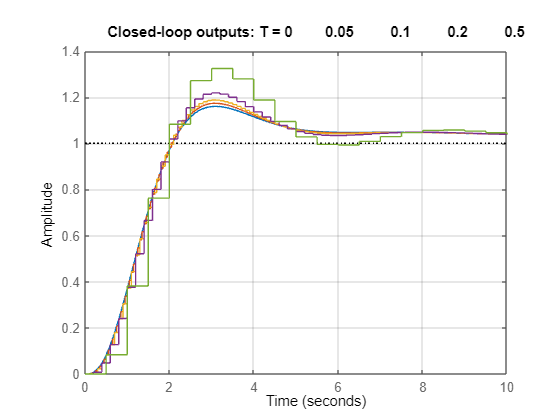

figure;clf
Gc = cell(1); Gcu = cell(1);
for k=1:nsample
    Gc{k} = feedback(Gsample{k}*Msample{k},1);
    Gcu{k} = feedback(Msample{k},Gsample{k});
    step(Gc{k},10);hold on;grid on
end
title(['Closed-loop output responses: T = ',num2str(samplerate)])

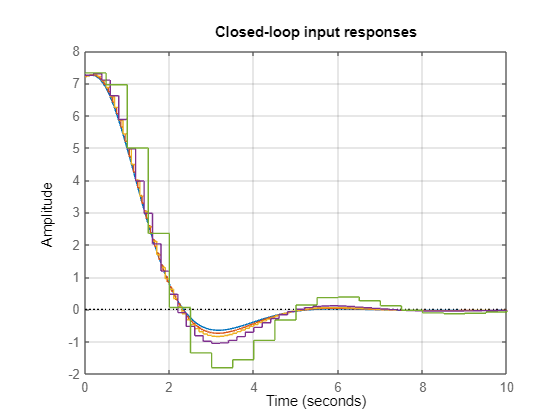


figure;clf
for k=1:nsample
   step(Gcu{k},10);hold on; grid on
end
title('Closed-loop input responses')

## 3. Additional comments on Nyquist frequencies

There is a limit to the frequencies at which a discretised system can have the frequency response computed that is dirrectly linked to the sample rate. This is not surprising as we cannot observe fast frequencies with slow sample rates. In essence the limit is given by:


$$\omega =\frac{\pi }{T}$$


The MATLAB ***bode.m*** function will illustrate these limits by vertical lines if one plots over a sufficient range of frequencies. For example see below.

disp('********************************************************** ')

********************************************************** 


disp('Extra observations in Section 3 below')

Extra observations in Section 3 below


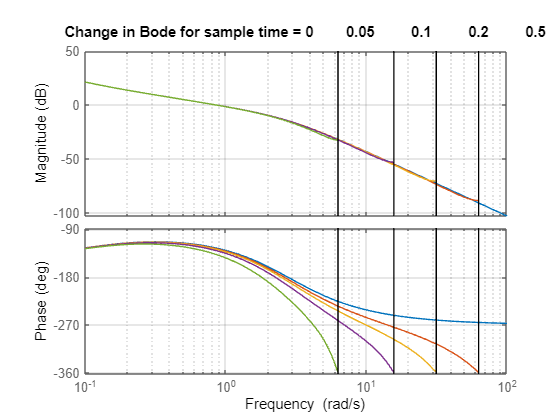

figure; clf
bode(G*M,{0.1,100});hold on
for k=2:nsample
    Gsample{k} = c2d(G,samplerate(k));
    Msample{k} = c2d(M,samplerate(k),'tustin');
    bode(Gsample{k}*Msample{k},{0.1,100}); hold on; grid on 
    [gm(k),pm(k)] = margin(Gsample{k}*Msample{k});
end
title(['Change in Bode for sample time = ',num2str(samplerate)])

nyqw = pi./samplerate(2:end);
disp(['Nyquist frequency given as: w = inf, ',num2str(nyqw)])

Nyquist frequency given as: w = inf, 62.8319      31.4159       15.708      6.28319
